# **VAJE 8**

load('s20501m.mat');
sig = val(1,:);
plot(sig);
Fs = 250;
fc = 1.0/(Fs/2);
[b, a] = butter(4,fc,'high')

b =     0.9677   -3.8708    5.8062   -3.8708    0.9677


a =     1.0000   -3.9343    5.8051   -3.8072    0.9364


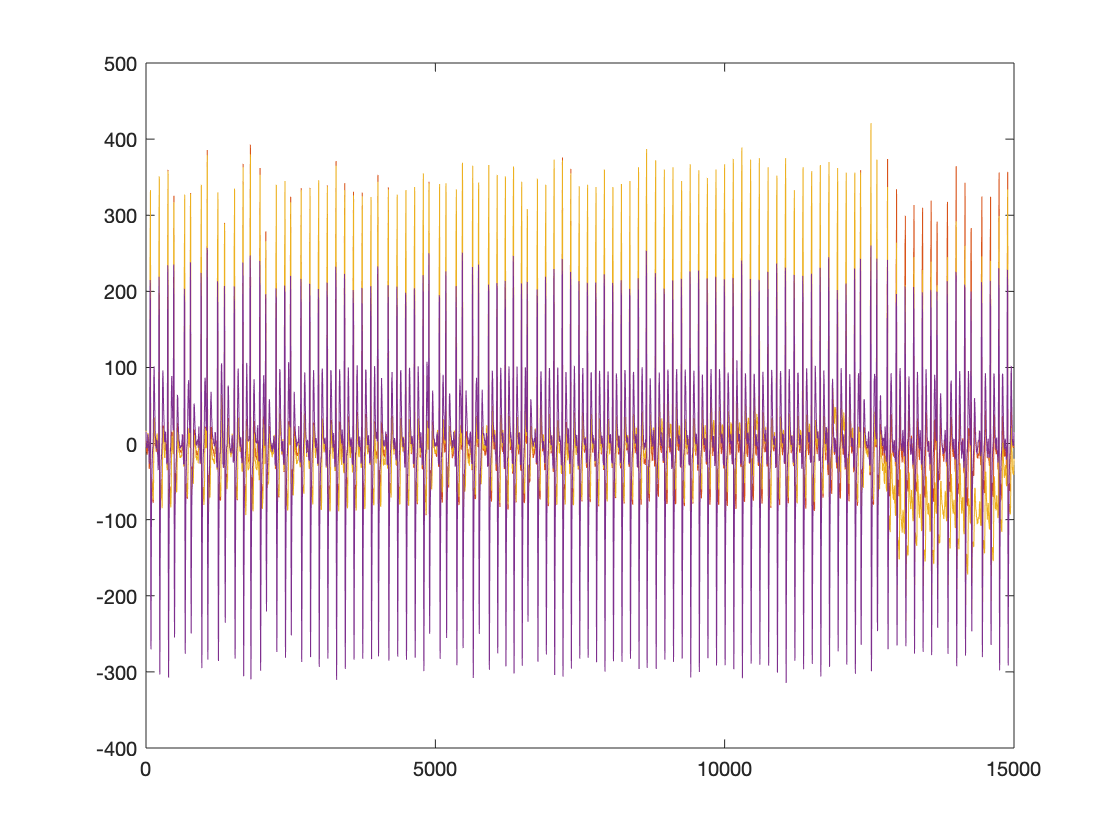

fsig = filter(b,a,sig);
hold on; plot(fsig); figure;

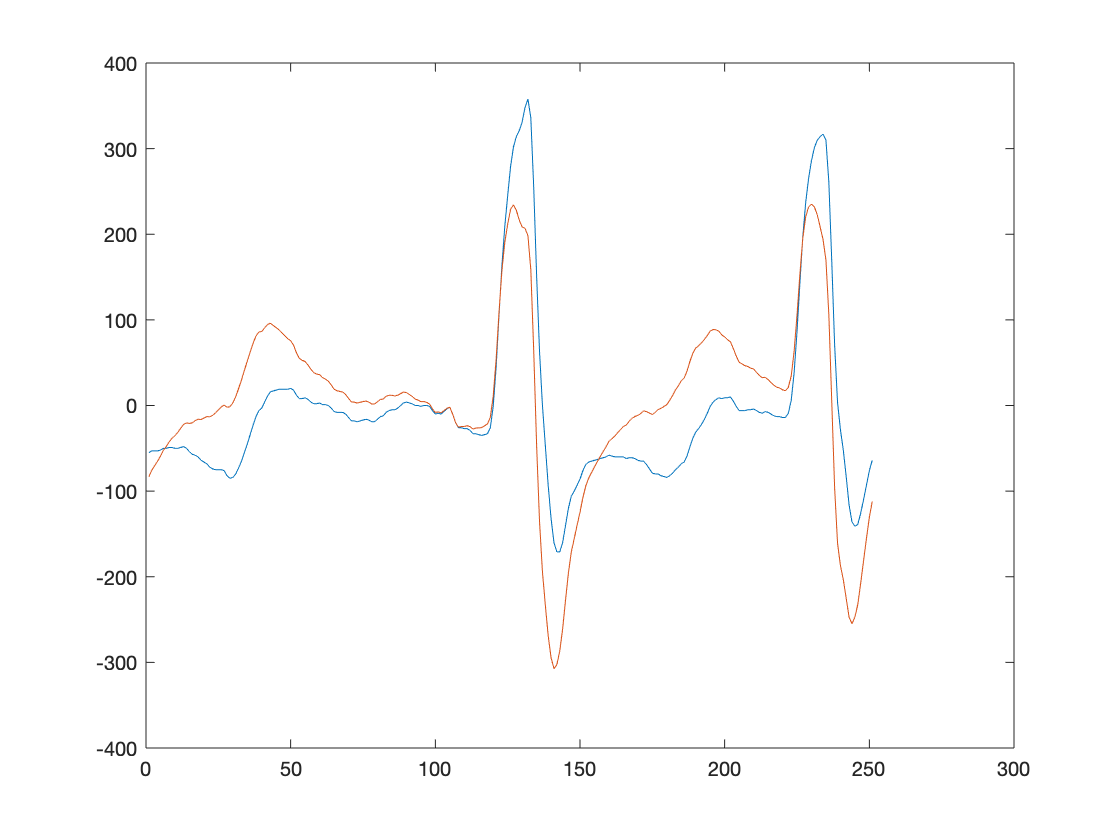

plot(sig(250:500)); hold on; plot(fsig(250:500));

1.) FIR:  b = fir1(N, fc, 'high'); N = 800

2.) IIR:  [b,a] = butter (N, fc, 'high'); N = 4

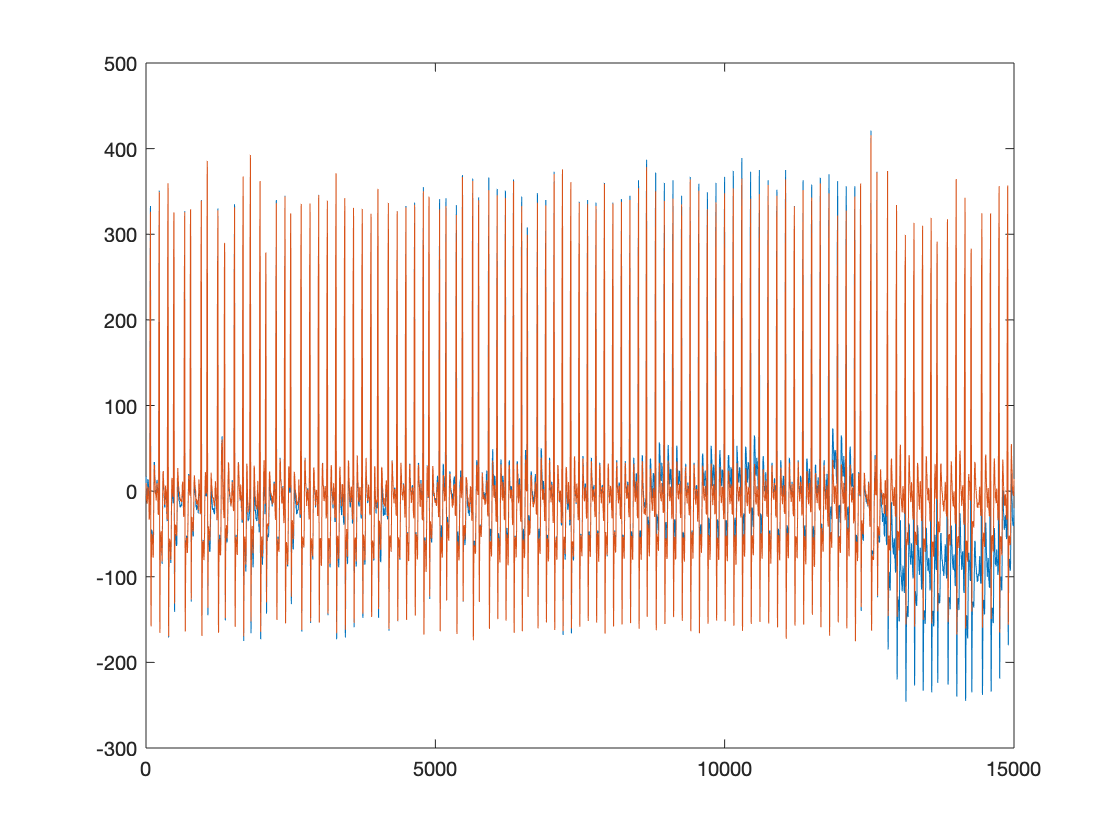

fsigf = flip(fsig);
fsig2 = filter(b,a,fsigf);
fsig2f = flip(fsig2);
figure;
plot(sig); hold on; plot(fsig2f); figure;

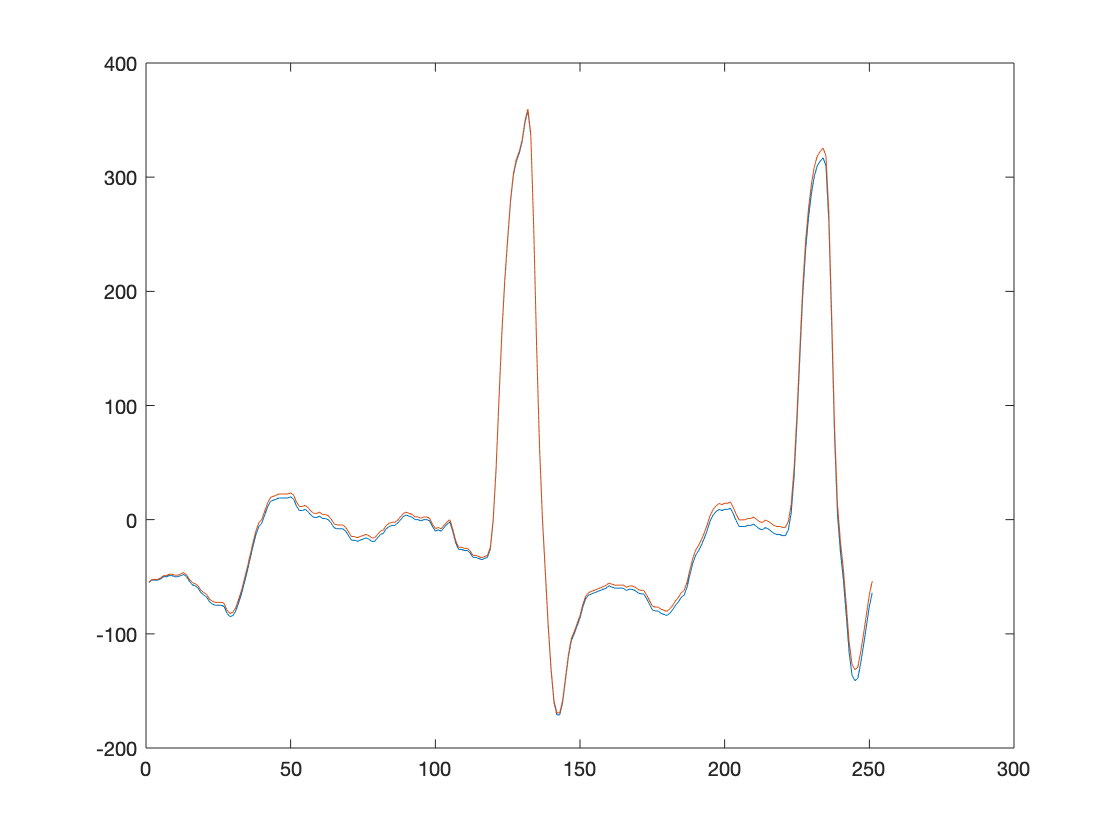

plot(sig(250:500)); hold on; plot(fsig2f(250:500));

 [B, fr, tm] = spectrogram (x, window, overlap, N, Fs)

load('s20011m.mat');
sig = val(1,:);
plot(sig);
